# 1.

a)

noise_img = imread("FensterNoisy.png");

noise_img = noise_img(:,:,1);

mask = ones(5, 1) / 5;

mask

mask =     0.2000
    0.2000
    0.2000
    0.2000
    0.2000


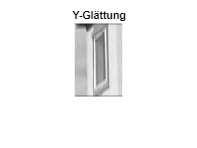


glatt_img = conv2(double(noise_img), mask, 'same');

glatt_img = uint8(glatt_img);
figure;
imshow(glatt_img);
title("Y-Glättung");

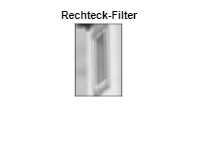


% b)
% 1 / 25 = 0.04
r_filt = [0.04 0.04 0.04 0.04 0.04; 0.04 0.04 0.04 0.04 0.04; 0.04 0.04 0.04 0.04 0.04; 0.04 0.04 0.04 0.04 0.04; 0.04 0.04 0.04 0.04 0.04,];
r_filt_img = conv2(double(noise_img), r_filt, 'same');

r_filt_img = uint8(r_filt_img);
figure;
imshow(r_filt_img);
title("Rechteck-Filter");

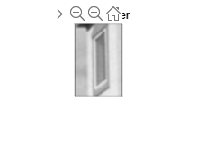


% Binomialfilter annäherung
gauss_filt = [1 4 6 4 1; 4 16 24 16 4; 6 24 36 24 6; 4 16 24 16 4; 1 4 6 4 1];
gauss_filt = double(gauss_filt) ./ 256; 
gauss_filt_img = conv2(double(noise_img), gauss_filt, 'same');
gauss_filt_img = uint8(gauss_filt_img);
figure;
imshow(gauss_filt_img);
title("Gauss-Filter");

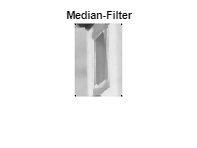


med_filt_img = medfilt2(noise_img, [5, 5]);


figure;
imshow(med_filt_img);
title("Median-Filter");


% c)
% Meiner Meinung ist das bild mit dem Gaußfilter am besten ist. Das bild
% mir dem einfachen Rechteckfilter weist leichte artefakte auf.

## 2.

a)

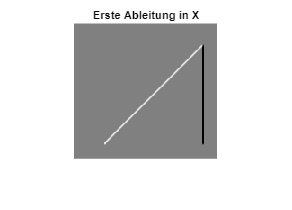

img = imread("Dreieck.png");

sobel_x = [-1 0 1; -2 0 2; -1 0 1];
sobel_x = double(sobel_x) .* 0.125;
s_img_x = conv2(double(img), sobel_x, 'same');
figure;
imshow(s_img_x, []), title("Erste Ableitung in X");

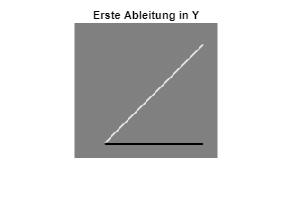


sobel_y = [-1 -2 -1; 0 0 0; 1 2 1];
sobel_y = double(sobel_y) .* 0.125;
s_img_y = conv2(double(img), sobel_y, 'same');
figure;
imshow(s_img_y, []), title("Erste Ableitung in Y");


% b)
% Im Bild s_img_x werden die Vertikalen Kanten angezeigt und im s_img_y
% dementsprechend die Horizontalen Kanten.

% c)
% Die Teile des Bildes die, in richtung der maske, von 0 -> 255 springen
% werden im Ergebnisbild positiv sein andersherung von 255 -> 0 wird das
% Ergebnisbild negativ.

% d)
% Der Gradient zeigt in die Richtung der größten Veränderung der Pixel an
% der Rechten Seite würde er dann nach rechts zeigen an der schräge nach
% links oben und unten nach unten.

% e)
grad = sqrt(s_img_y.^2 + s_img_x.^2);
grad

grad =   135.2342  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000  127.5000
  127.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

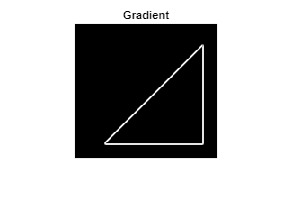

figure;
imshow(grad, []);
title("Gradient");

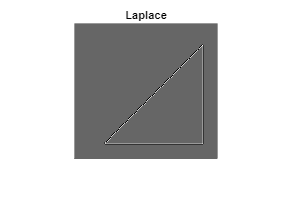


% f)
laplace = [0 1 0; 1 -4 1; 0 1 0];
lap_img = conv2(double(img), laplace, 'same');
figure;
imshow(lap_img, []);
title('Laplace');


% g)
moon = imread("Mond.png");
sharp = [1 1 1; 1 -8 1; 1 1 1];
sharp

sharp =      1     1     1
     1    -8     1
     1     1     1


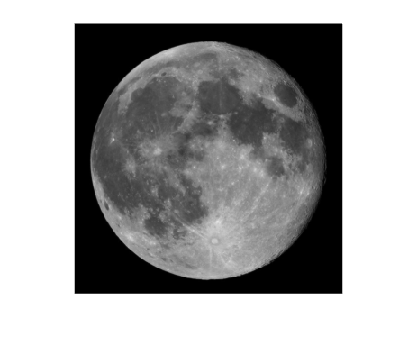

sharp_moon = conv2(double(moon), sharp, 'same');
sharp_moon = uint8(sharp_moon);
x = moon - 0.3 .* sharp_moon;
figure;
imshow(moon);

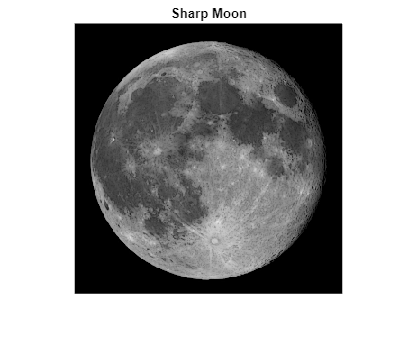

figure;
imshow(x);
title("Sharp Moon");

## 3.

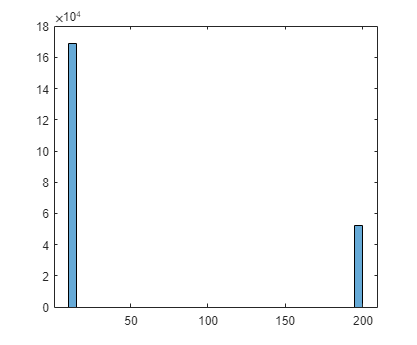

hist =   Histogram with properties:

             Data: [377×586 uint8]
           Values: [168679 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 52243]
          NumBins: 38
         BinEdges: [10 15 20 25 30 35 40 45 50 55 60 65 70 75 80 85 90 95 100 105 110 115 120 125 130 135 140 145 150 155 160 165 170 175 180 185 190 195 200]
         BinWidth: 5
        BinLimits: [10 200]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


img = imread("BIVr.png");
% a)
% Das Bild hat 2 verschiedene Grauwerte 10 und 200
hist = histogram(img)

sum(hist.Values > 0)

ans = 2

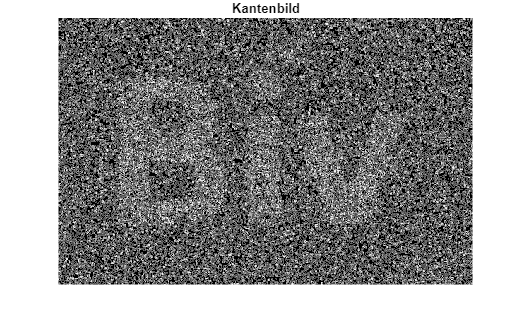


% b)
% Um ein Kantenbild zu erhalten welches die Stärke der Kante zeigt
% verwenden wir den Sobel Operator.
sobel_x = [-1 0 1; -2, 0, 2; -1, 0, 1];
s_img_x = conv2(double(img), sobel_x, 'same');
sobel_y = [-1, -2, -1; 0, 0, 0; 1, 2, 1];
s_img_y = conv2(double(img), sobel_y, 'same');

kanten_img = sqrt(s_img_y.^2 + s_img_x.^2);
figure;
imshow(kanten_img,[]);
title("Kantenbild");

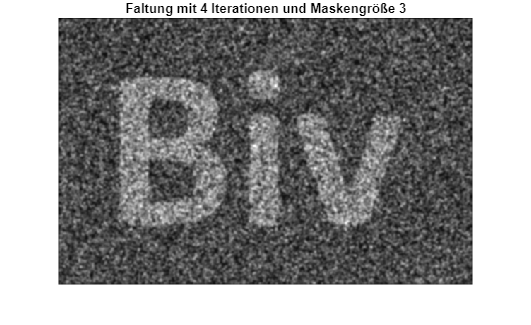


% c)
faltung(4, img);

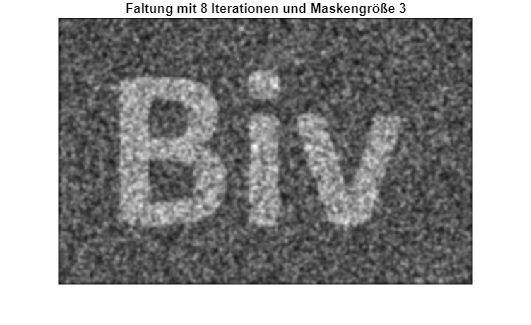

faltung(8, img);

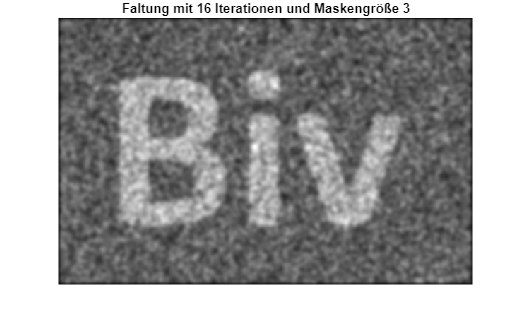

faltung(16, img);

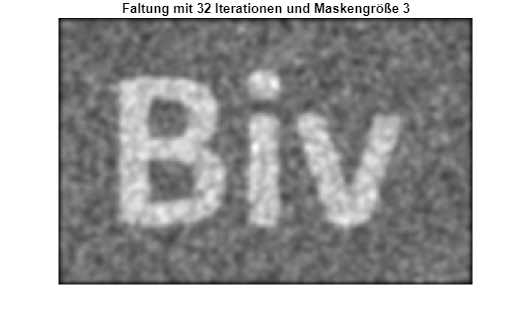

max_faltung = faltung(32, img);

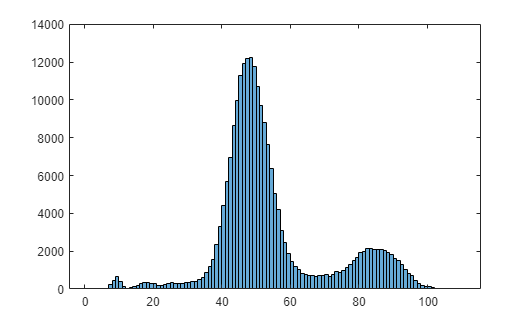



% d)
% Durch die Wiederholte Faltung entstehen deutlich mehr Grauwerte zudem
% verschwinden die extremen (200) da durch das ständige mitteln die Werte
% sich in der Mitte anhäufen.
histogram(max_faltung);

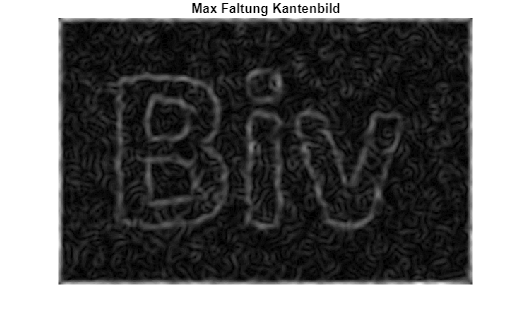


% e)
sobel_x = [-1 0 1; -2, 0, 2; -1, 0, 1];
s_mimg_x = conv2(double(max_faltung), sobel_x, 'same');
sobel_y = [-1, -2, -1; 0, 0, 0; 1, 2, 1];
s_mimg_y = conv2(double(max_faltung), sobel_y, 'same');

m_f_kanten_img = sqrt(s_mimg_y.^2 + s_mimg_x.^2);
figure;
imshow(m_f_kanten_img, []);
title("Max Faltung Kantenbild");

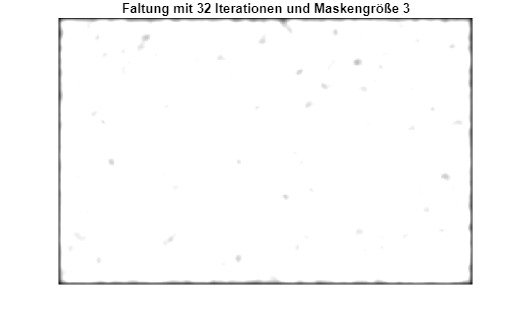


% f)
% Wenn man das Kantenbild 32-mal glättet verschwimmen die Kanten und
% verschwinden langsam. Im geglätteten Bild können die Kanten jedoch noch
% identifiziert werden.
faltung(32, kanten_img);

## 4.

a) Die deutlichkeit (stärke) einer Kante können wir mit dem Sobel.Operator bestimmen.

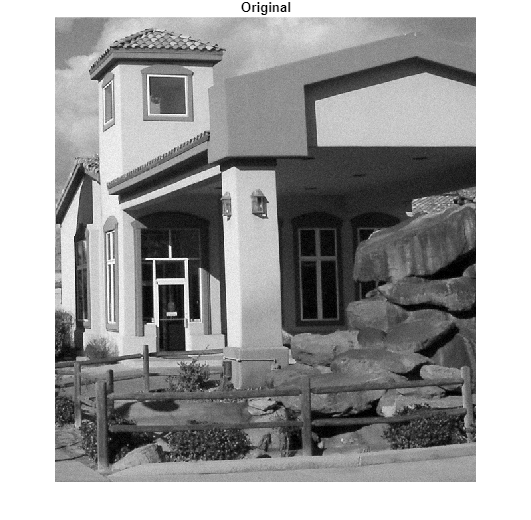

img = imread("HausNoisy.png");
figure;
imshow(img), title("Original");

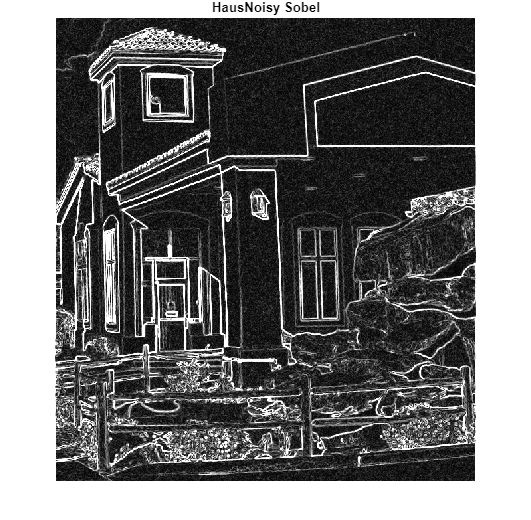


sobel_x = [-1 0 1; -2, 0, 2; -1, 0, 1];
s_mimg_x = conv2(double(img), sobel_x, 'same');
sobel_y = [-1, -2, -1; 0, 0, 0; 1, 2, 1];
s_mimg_y = conv2(double(img), sobel_y, 'same');
sobel_img = sqrt(s_mimg_y.^2 + s_mimg_x.^2);
sobel_img = uint8(sobel_img);
figure;
imshow(sobel_img), title("HausNoisy Sobel");

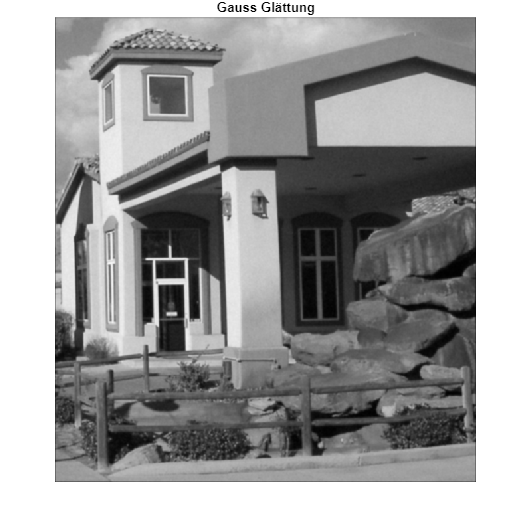


% b)
bin_img = sobel_img > 200;
bin_img = uint8(bin_img);

% c)
gauss_filt = fspecial("gaussian", 5, 1);
d_img = double(img);
filtered = conv2(d_img, gauss_filt, 'same');
filtered = uint8(filtered);
figure;
imshow(filtered), title("Gauss Glättung");

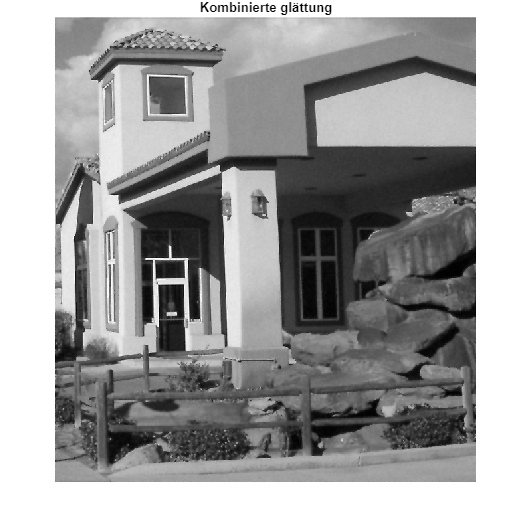

filtered = filtered .* (1-bin_img);
filtered = filtered + (img .* bin_img);

figure;
imshow(filtered), title("Kombinierte glättung");


% d)
% Die Dachziegel wirken bei der inhomogenen Glättung weniger verwaschen vor
% speziell die Kanten sind besser zu erkennen.


function glatt = faltung(iterations, img) 
    gauss_filt = fspecial("gaussian", 3, 1);
    filtered_img = img;
    for i = 1:iterations 
        filtered_img = conv2(double(filtered_img), gauss_filt, 'same');
    end
    filtered_img = uint8(filtered_img);
    figure;
    imshow(filtered_img, []);
    title(sprintf("Faltung mit %d Iterationen und Maskengröße 3", iterations));
    glatt = filtered_img;
end